# Principles of MATLAB Programming

Here are some basic concepts described for programming in MATLAB. 

## Strings

Quotation Marks and apostophes denote strings in MATLAB.

a = 'hello world'

a = 'hello world'

b = "hello world"

b = "hello world"

a==b

ans = logical
   1


## Array Median

a = rand(1,11);
b = sort(a);
c = b(1,ceil(end/2));
c % c is the value equidistant from both ends of array: median

c = 0.7234


A = [0 1 1 1 2];
A(1,ceil(end/2))

ans = 1

mean(A)

ans = 1

median(A)

ans = 1

mode(A)

ans = 1

## Profiler

The MATLAB profiler tracks the execution time for a program. This can be accomplished using the commands tic and toc to start and stop the stopwatch for MATLAB.

tic 
a = rand(1,11);
b = sort(a);
c = b(1,ceil(end/2));
c % c is the value equidistant from both ends of array: median

c = 0.5803

toc

Elapsed time is 0.006157 seconds.


## While Loops

The syntax for a while loop is described below.

a = 0;
while a < 5
    a = a+1;
end

## Code Sections

To split the code into sections use the %% notation

%% Title of Section
% Print fizz buzz 10 times
hash = ['fizz ','buzz '];
repmat(hash,1,10)

ans = 'fizz buzz fizz buzz fizz buzz fizz buzz fizz buzz fizz buzz fizz buzz fizz buzz fizz buzz fizz buzz '


%% Section 2
% Print odd numbers between 1 and 100
hash = [];
for i = 1:100
    if mod(i,2)==1
        hash(end+1)=i;
    end
end
hash

hash =      1     3     5     7     9    11    13    15    17    19    21    23    25    27    29    31    33    35    37    39    41    43    45    47    49    51    53    55    57    59    61    63    65    67    69    71    73    75    77    79    81    83    85    87    89    91    93    95    97    99


## Element-wise Operations

The dot notation is used for 

- structural field access, 

- decimal points, and 

- element-wise operations

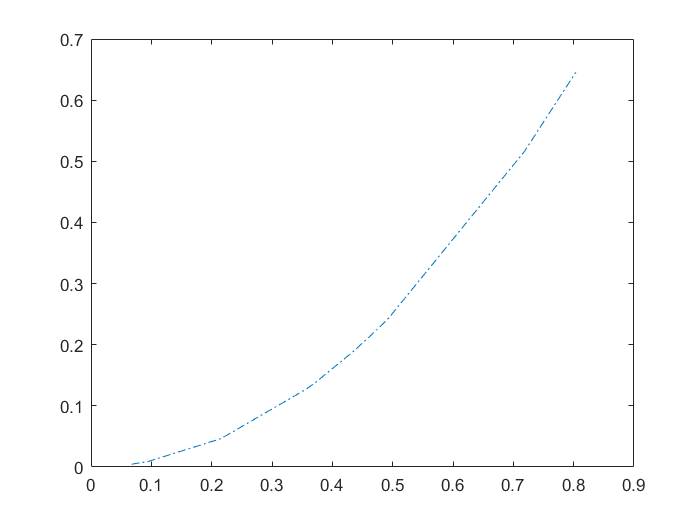

x = sort(1.01*rand(1,11));
y = x.^2;
new_plot = plot(x,y);
new_plot.LineStyle = '-.';

# Structures

Explore the different object structures available in MATLAB.

## Structs

dog = struct();
dog.name = 'Bindy';
dog.breed = 'border collie';
dog.weight = 32;
dog

dog = struct with fields:
      name: 'Bindy'
     breed: 'border collie'
    weight: 32


## Cell Arrays

Create a cell array that holds different types of objects.

c = {'hello world' {'hello'} 'goodbye' [1 2 3]}

c = 1×4 cell array
    {'hello world'}    {1×1 cell}    {'goodbye'}    {[1 2 3]}


## Concatenation

Append values to the end of cell array.

c{length(c)+1}='a';

## Set Difference

Find the set difference of cell arrays.

C = {'dog' 'cat' 'mouse'}

C = 1×3 cell array
    {'dog'}    {'cat'}    {'mouse'}


D = {'cow' 'piranha' 'mouse'}

D = 1×3 cell array
    {'cow'}    {'piranha'}    {'mouse'}


E = setdiff(C,D)

E = 1×2 cell array
    {'cat'}    {'dog'}


## Joins

Return a cell array from a menu that meets a given criteria.

menu = {'hot dog' 'corn dog' 'regular burger' 'cheeseburger' 'veggie burger'};
menu(contains(menu,'burger'))

ans = 1×3 cell array
    {'regular burger'}    {'cheeseburger'}    {'veggie burger'}


menu_string = cell2mat(join(menu,newline))

menu_string =     'hot dog
     corn dog
     regular burger
     cheeseburger
     veggie burger'


## Adding Vectors and Matrices

Use the repmat() function to manipulate matrices. Add a vector to each row of a matrix.

a = ones(4,4) % a is a matrix

a =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


b = [1 2 3 4] % b is a vector

b =      1     2     3     4


a = a + repmat(b,4,1) % add b to each row of a

a =      2     3     4     5
     2     3     4     5
     2     3     4     5
     2     3     4     5


## Replace Characters

Replace all the a's with o's.

fruit = {'apple', 'orange', ' banana', ' tomato'};
for i = 1:length(fruit)
    fruit{i}(fruit{i}=='a')='o';
end
fruit

fruit = 1×4 cell array
    {'opple'}    {'oronge'}    {' bonono'}    {' tomoto'}


## Logical Indexing

There are different ways to index an array in MATLAB.

a = 1:10;
b = a(a~=11)

b =      1     2     3     4     5     6     7     8     9    10


b = a(a==1)

b = 1

b = a(a>6 & a<9)

b =      7     8


b = a(a|1)

b =      1     2     3     4     5     6     7     8     9    10


## Logical Arrays

Create a logical array that is 1 if the element in passwords contains a digit and 0 if it does not.

passwords = {'abcd' '1234' 'qwerty' 'lovel'};
cellfun(@(x)~isempty(regexp(x,'\d')),passwords)

ans = 1×4 logical array
   0   1   0   0


## Switching

Here is the syntax for switching in MATLAB.

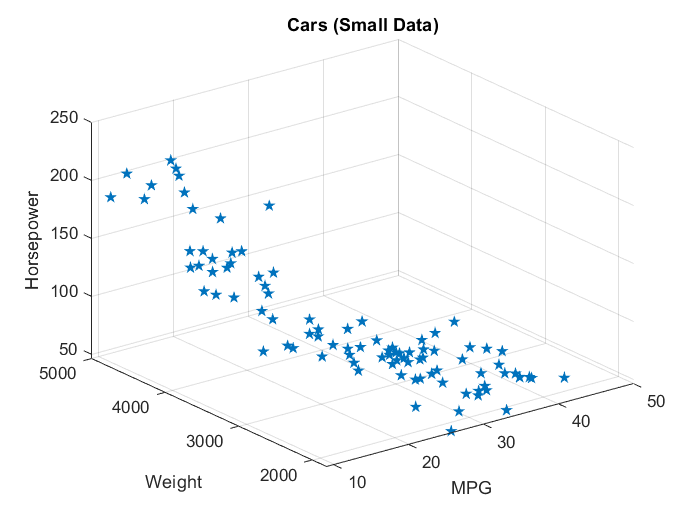

x = 7;
switch x
    case 2
        disp('two')
    otherwise
        disp('not two')
end

# Mathematical and Graphical Operations

## Figures

Use the figure() command to open a new figure window.

load carsmall
figure();
scatter3(MPG,Weight,Horsepower,'filled',"pentagram","MarkerEdgeColor","flat")
xlabel('MPG')

S =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [101×101 double]
           YData: [101×101 double]
           ZData: [101×101 double]
           CData: [101×101 double]

  Show all properties


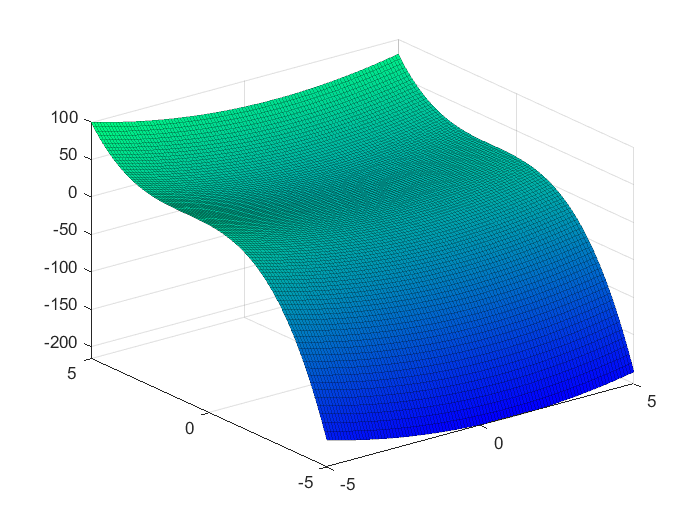

ylabel('Weight')
zlabel('Horsepower')

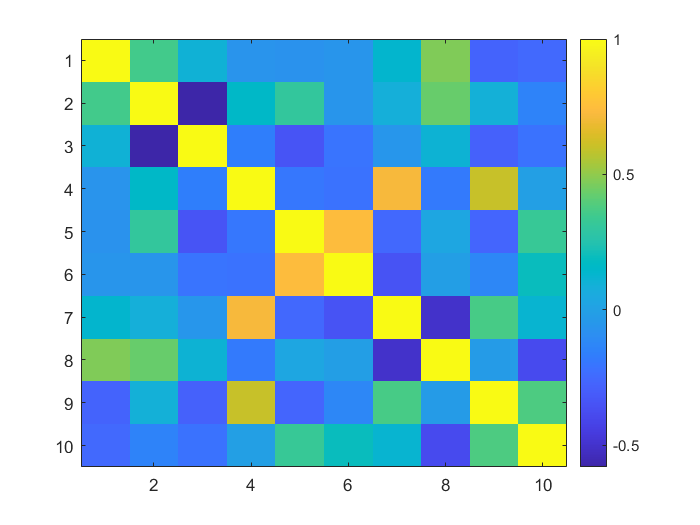

title('Cars (Small Data)')

new_fig = figure();
[X,Y]=meshgrid(-5:0.1:5,-5:0.1:5);
Z = (X-1).^2 + (Y-1).^3;
S = surf(X,Y,Z)
new_fig.Colormap = winter;
S.EdgeAlpha = 0.25;

## imagesc()

Use the function imagesc() to create a density grid for your data.

figure();
x = rand(10,10);
r = corrcoef(x);
imagesc(r)
colorbar

## Root Finding

Find the roots of a polynomial.

figure();
poly_fun = @(x) x.^2 +2*x-4;
t = -10:0.01:10;

S =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 36
          LineWidth: 0.5000
              XData: [-3.2361 1.2361]
              YData: [0 -4.4409e-16]
              ZData: [1×0 double]
              CData: [0.9290 0.6940 0.1250]

  Show all properties


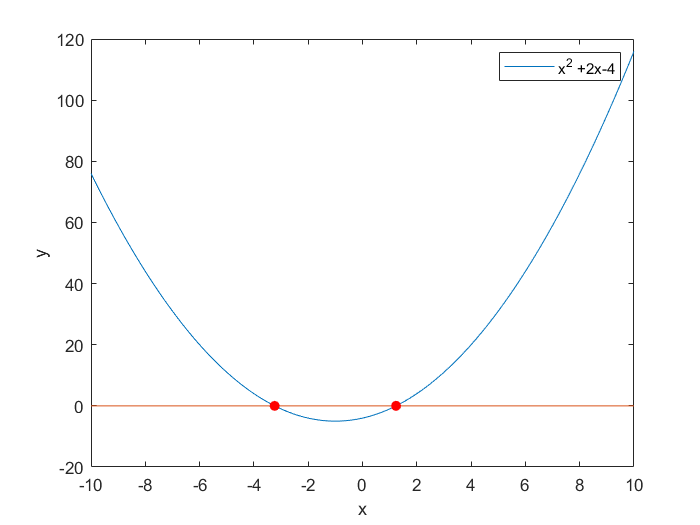

plot(t,poly_fun(t))
t0 = roots([1 2 -4]);
hold on
plot(t,zeros(1,length(t))) % x-axis
S=scatter(t0,poly_fun(t0),'filled')

S.MarkerFaceColor = 'red';
hold off
xlabel('x')
ylabel('y')
legend('x^2 +2x-4')

## Factorials

Look at the following ways to calculate 10! = 3628800.

%  10!
f10 = 1;
for i = 1:10
    f10 = f10 * i;

f10 = 3628800

end
f10


f10 = 3628800

%  10!
f10 = factorial(10)


f10 = 3628800

%  10!
f10 = prod(1:10)

% wrong factorial 10!
f10 = 1;
i = 1;
while i<=10
    i = i+1; % iterate in wrong place
    f10 = i*f10;

f10 = 39916800

end
f10

## Imaginary Numbers

The symbol i stands for the imaginary unit.

clear all
i

ans = 0.0000 + 1.0000i

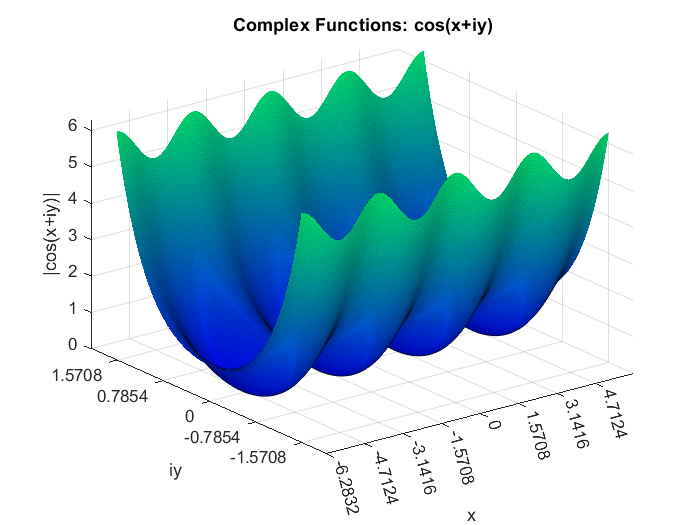

new_fig = figure();
[x,y] = meshgrid(-2*pi:0.01:2*pi,-pi/2:0.01:pi/2);
z = cos(x+i*y);
S=surf(x,y,real(z).^2+imag(z).^2);
new_fig.Colormap = winter;
S.EdgeAlpha = 0.05;
xlabel('x')
ylabel('iy')
zlabel('|cos(x+iy)|')
title('Complex Functions: cos(x+iy)')
xticks(-2*pi:pi/2:2*pi)
yticks(-pi/2:pi/4:pi/2)

## Identity Matrices

Here are some different ways for constructing the identity matrix in MATLAB.

a = rand(5);
round(a*inv(a))

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


diag(ones(5,1))

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


eye(5)

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


# Probability and Statistics

Use the built-in MATLAB functions to analyze data.

## Simulate a normally distributed population

Simulate 100 samples from a normal distribution with the same mean and variance as the weights of cars in carbig.mat

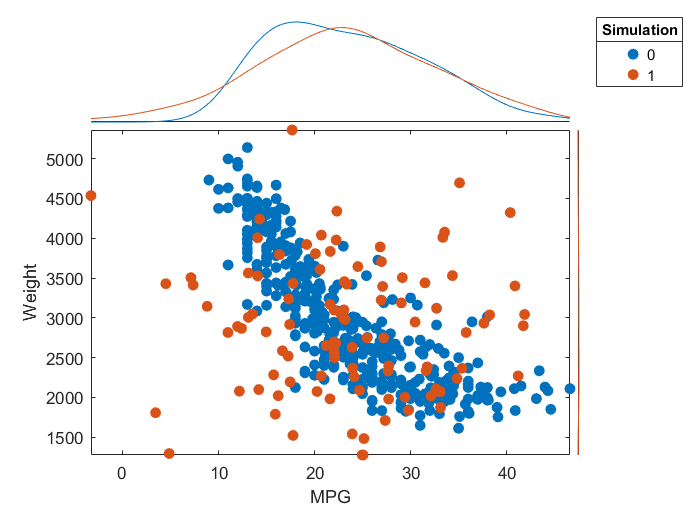

clear all
load carbig.mat
sim_Weight = mean(Weight)+std(Weight)*randn(100,1);
sim_MPG = nanmean(MPG)+nanstd(MPG)*randn(100,1);
IsSim = [zeros(length(Weight),1);ones(100,1)];
tbl = table(Weight,MPG);
sim_tbl = table(sim_Weight,sim_MPG);
sim_tbl.Properties.VariableNames{'sim_Weight'} = 'Weight';
sim_tbl.Properties.VariableNames{'sim_MPG'} = 'MPG';
tbl = [tbl; sim_tbl];
tbl.Simulation = IsSim;
figure();
s = scatterhistogram(tbl,'MPG','Weight',...
    'GroupVariable','Simulation',...
    'HistogramDisplayStyle','smooth', ...
    'LineStyle','-');

## Remove Average Values

Remove the mean values from the Weight data.

Weight_nomean = bsxfun(@minus,Weight,mean(Weight))

Weight_nomean = 	1.0e+03 *

    0.5246
    0.7136
    0.4566
    0.4536
    0.4696
    1.3616
    1.3746
    1.3326
    1.4456
    0.8706


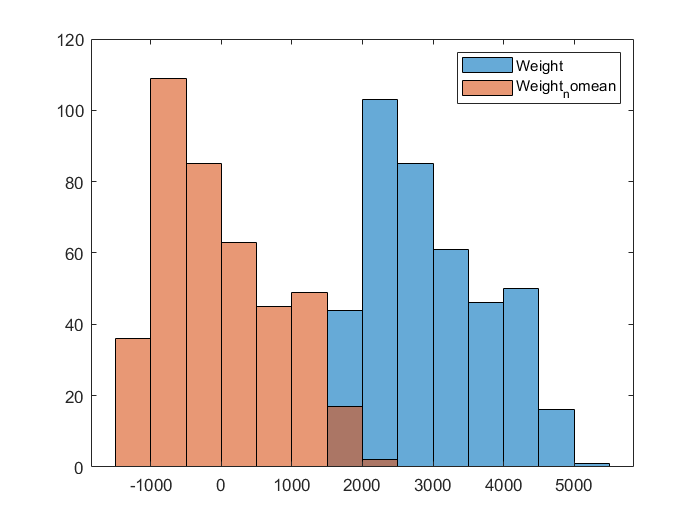

histogram(Weight)
hold on
histogram(Weight_nomean)
hold off
legend

#### Return the mean values of each array in a cell

b = cellfun(@(m) nanmean(m(:)),{Weight,MPG,Horsepower})

b = 	1.0e+03 *

    2.9794    0.0235    0.1051


## Write Variables to .mat file

Save our variables in a .mat file.

save('Weight_nomean.mat','Weight_nomean','sim_Weight')

## Uniform Distribution

To generate a random number from the uniform distribution U[0,1] use rand().

rng(1) % set seed
rand()

ans = 0.4170

## Seeds

Select a new random seed based on the current time and save the current settings of the random number generator

rng_settings_curr = rng('shuffle')

rng_settings_curr = struct with fields:
     Type: 'twister'
     Seed: 1
    State: [625×1 uint32]


rng(floor(now))
rng_settings_curr=rng()

rng_settings_curr = struct with fields:
     Type: 'twister'
     Seed: 738550
    State: [625×1 uint32]


## Random Sampling

There are multiple ways to randomly sample from data.

load carbig.mat

% use randi
a_sample = Acceleration(randi(size(Acceleration,1),100,1))

a_sample =    13.5000
   19.4000
   14.0000
   14.5000
   14.9000
   16.9000
   15.0000
   14.0000
   16.4000
   17.6000


% use randperm
b_sample = Horsepower(randperm(size(Horsepower,1),100))

b_sample =    100
   110
    88
    85
   130
    97
    92
   130
    79
    71


% use datasample
c_sample = datasample(Cylinders,100)

c_sample =      6
     8
     6
     4
     4
     4
     4
     4
     8
     8


## Linear Regression

Use the regress() function to fit a linear regression model.

x = rand(1,100)';
X = [ones(size(x)),x];

% data satisfies assumptions of linear regression
y = 0.15*x + 0.1 + 0.025*randn(size(x));

% use regress()
[b,c] = regress(y,X)

b =     0.1086
    0.1420


c =     0.0970    0.1202
    0.1225    0.1614


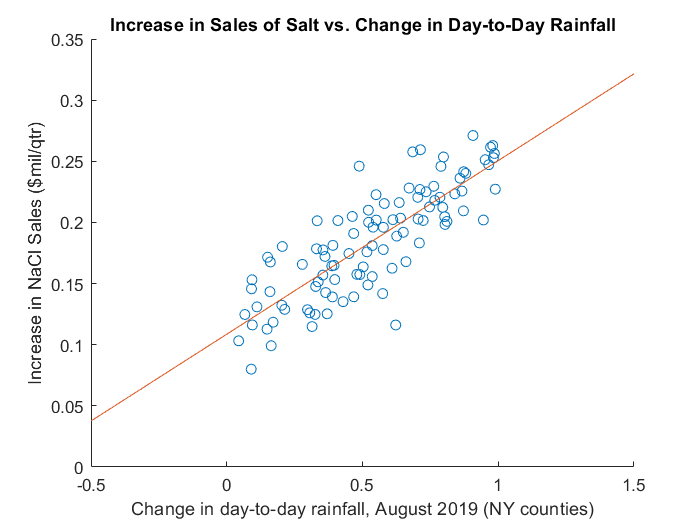


% scatter data
scatter(x,y)

% fit model
z = -0.5:0.01:1.5;
hold on
plot(z,b(1)+b(2)*z)
hold off

% label plot
xlabel('Change in day-to-day rainfall, August 2019 (NY counties)')
ylabel('Increase in NaCl Sales ($mil/qtr)')
title('Increase in Sales of Salt vs. Change in Day-to-Day Rainfall')

## Patient Data

clear all
load patients.mat
x = Weight;
y = Diastolic./Systolic;
coeff_line = polyfit(x,y,1)

coeff_line =     0.0003    0.6367


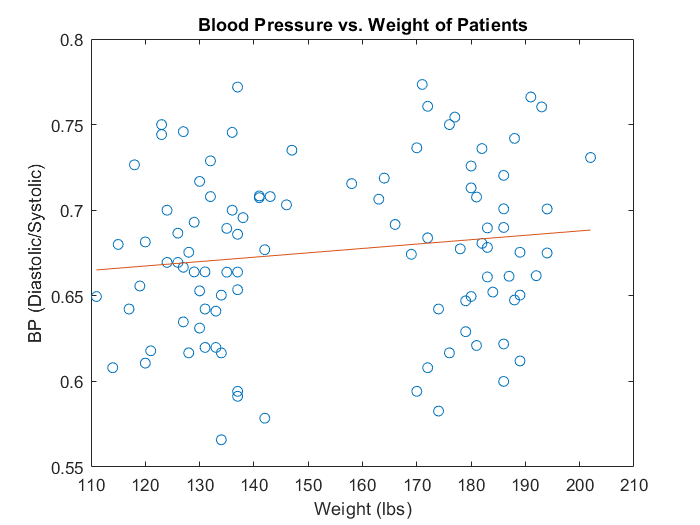

x_line = floor(min(x)):0.1:ceil(max(x));
y_line = polyval(coeff_line,x_line);
figure();
plot(x,y,'o');
hold on
plot(x_line,y_line)
title('Blood Pressure vs. Weight of Patients')
ylabel('BP (Diastolic/Systolic)')
xlabel('Weight (lbs)')